ulog = ulogreader("jet_test/jet6_sw430.ulg");
engine_status_msg = readTopicMsgs(ulog,"TopicNames",'engine_status', ...
    'Time',[ulog.StartTime, ulog.EndTime]);
engine_status = engine_status_msg.TopicMessages{1,1};

jet_controller_msg = readTopicMsgs(ulog,"TopicNames",'jet_controller', ...
    'Time',[ulog.StartTime, ulog.EndTime]);
jet_controller = jet_controller_msg.TopicMessages{1,1};


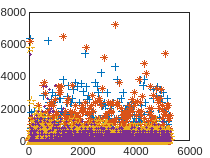

figure;
plot(diff(engine_status.servo_timestamp(:,1)) ,'+');
hold on;
plot(diff(engine_status.servo_timestamp(:,2)) ,'*');
plot(diff(engine_status.servo_timestamp(:,3)) ,'p');
plot(diff(engine_status.servo_timestamp(:,4)) ,'.');
hold off;

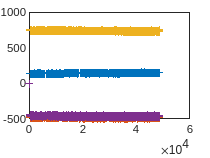


figure;
plot(engine_status.servo_timestamp(:,1)*1e-1,engine_status.pos_sensor(:,1),'+');
hold on;
plot(engine_status.servo_timestamp(:,2)*1e-1,engine_status.pos_sensor(:,2),'+');
plot(engine_status.servo_timestamp(:,3)*1e-1,engine_status.pos_sensor(:,3),'+');
plot(engine_status.servo_timestamp(:,4)*1e-1,engine_status.pos_sensor(:,4),'+');
hold off;

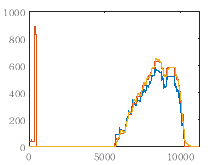

num = 6;
throttle_ref = jet_controller.throttle_ref(:,num);
rpm_fb = jet_controller.rpm_fb(:,num);
output = jet_controller.output(:,num);

figure;
plot(output);
hold on;
plot(throttle_ref);
plot(rpm_fb);
hold off;